# Cálculo de coeficiente de convección de tanque en reposo

clc
clear
close all

## Carga de datos

data=load("Mapeo_temp100621.txt");
t=data(:,1); %Columna de tiempo
t_max=length(t);
T_TCW=data(:,15:17); % Temperaturas al interior del tanque [°C]
T_amb=data(:,72); % Temperatura ambiente
ini_enf=0;
fin_enf=8; % Hora final de enfriamiento

## Características del tanque

V_tanque=2000; %Volumen de tanque [L]
epsilon=3; %Espesor aislamiento tanque [inch]
k_cond=0.00006; % Conductividad térmica [kW/mK]
Cpw=4.187; %Calor específico de tanque [kJ/kgK]
mwt=V_tanque*.998; %Masa de agua [kg]
diametro=1.3; % Diámetro de tanque [m]
area_base=pi*diametro^2/4; % Área de base de tanque [m2]
altura=(V_tanque/1000)/(area_base); % Altura calculada de tanque [m]
perim=pi*diametro; % Perímetro de tanque [m]
Area_tanque=perim*altura; % Área de tanque [m2]

Estimación de valor de tiempo

  for i=1:t_max %Localización de tiempo de inicio y fin de prueba
      if t(i)<=ini_enf
            t_ini_enf=i-1;
        end 
        if t(i)<=fin_enf
            t_fin_enf=i;
        end    
  end

##  Elaboración  de ajuste polinomial

grado_pol=1;% grado del polinomio
T_TCW_prom=mean(T_TCW,2);%Temperatura promedio tanque por renglón
zp1=polyfit(t(t_ini_enf:t_fin_enf),T_TCW_prom(t_ini_enf:t_fin_enf),grado_pol); % Ajuste lineal
T_TCW_poly=polyval(zp1,t(t_ini_enf:t_fin_enf)); %Evaluación del polinomio
R2T= 1-var(T_TCW_prom(t_ini_enf:t_fin_enf)-T_TCW_poly)/var(T_TCW_prom(t_ini_enf:t_fin_enf)); %Coeficiente de correlación
fprintf('El polinomio de ajuste es:\n y=%2.4fx+%2.2f',zp1(1),zp1(2))

El polinomio de ajuste es:
 y=-0.5353x+73.81

fprintf('el coecifiente de correlación es %2.4f',R2T)

el coecifiente de correlación es 0.9986

## Cálculo de pendiente

syms x
pol=zp1(1)*x+zp1(2); % Creación del polinomio
m=double(diff(pol)); %Pendiente con derivada
T_TCW_avg=mean(T_TCW_prom(t_ini_enf:t_fin_enf)); %Temperatura promedio de la prueba
T_TCW_ini=T_TCW_prom(t_ini_enf); %Temperatura inicial de prueba
T_TCW_fin=T_TCW_prom(t_fin_enf); %Temperatura final de pueba
m2=(T_TCW_fin-T_TCW_ini)/(8);
T_amb_prom=mean(T_amb);

fprintf('La temperatura inicial es:%2.2f°C',T_TCW_ini);

La temperatura inicial es:73.74°C

fprintf('La temperatura final es:%2.2f°C',T_TCW_fin)

La temperatura final es:69.51°C

fprintf('La temperatura promedio es:%2.2f°C',T_TCW_avg)

La temperatura promedio es:71.67°C

fprintf('La temperatura ambiente promedio es:%2.2f°C',T_amb_prom)

La temperatura ambiente promedio es:27.98°C

## Cálculo del coeficiente convectivo


$$h_{\textrm{conv}} =\frac{m_{w\;\textrm{Tank}} \;C_{\textrm{Pw}} }{A_{\textrm{tank}} \;\left(T_{\textrm{amb}} -T_w \right)}\frac{d{\mathrm{T}}_w }{\textrm{dt}}-\frac{k_{\textrm{eff}} }{\varepsilon_{\textrm{tot}} }$$


h_conv=(mwt*Cpw)/(Area_tanque*(T_amb_prom-T_TCW_avg))*m/3600-(k_cond/(0.0254*epsilon));
fprintf('El coef de convección es de %1.4f [W/m^2K]',h_conv*1000)

El coef de convección es de 3.8347 [W/m^2K]

## Elaboración de gráficos

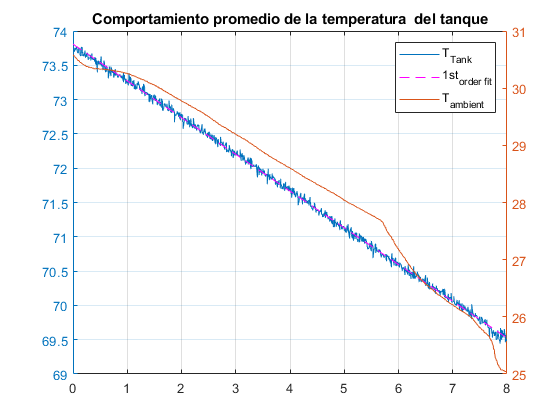

yyaxis left
plot(t(t_ini_enf:t_fin_enf),T_TCW_prom(t_ini_enf:t_fin_enf),t(t_ini_enf:t_fin_enf),T_TCW_poly,'m--')
grid on;title('Comportamiento promedio de la temperatura  del tanque')
 
yyaxis right
plot(t(t_ini_enf:t_fin_enf),T_amb(t_ini_enf:t_fin_enf))

legend('T_{Tank}','1st_{order fit}','T_{ambient}')